% Define calibration parameters
A = [1.380173, -0.014825, 0.000591; ...
    -0.014825, 1.273212, -0.017644; ...
    0.000591, -0.017644, 1.326894];
b = [-21.291563; -0.059196; -7.383874];

% Add a black circle with radius 9.8066 to show ideal gravity vector values
theta = linspace(0, 2*pi, 100);  % 100 points around the circle
radius = 9.8066;  % radius of the circle

% Plot colours
RGB_Orange = [0.9290 0.6940 0.1250];
RGB_Blue = [0 0.4470 0.7410];

% Marker size
msize = 3.5;

% Parametric equations to get x and y coordinates of the circle
x_circle = radius * cos(theta);
y_circle = radius * sin(theta);

% Read raw data and apply calibration
rawData = dlmread('magdata.txt', '\t'); %#ok<DLMRD> 
units = 'm/s^2';  % units of accelerometer measurements (used for axis labels)

N = size(rawData, 1);
calibData = zeros(N, 3);

for i = 1:N
    currMeas = [rawData(i, 1), rawData(i, 2), rawData(i, 3)]';
    calibData(i, :) = A * (currMeas - b);
end

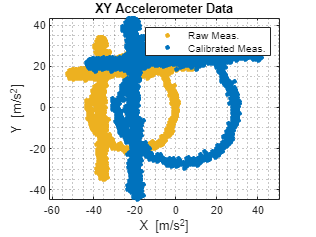

% Plot XY data
figure;
plot(rawData(:, 1), rawData(:, 2), 'o', 'DisplayName', 'Raw Meas.', MarkerFaceColor=RGB_Orange, MarkerEdgeColor=RGB_Orange, MarkerSize=msize);
hold on;
plot(calibData(:, 1), calibData(:, 2), 'o', 'DisplayName', 'Calibrated Meas.', MarkerFaceColor=RGB_Blue, MarkerEdgeColor=RGB_Blue, MarkerSize=msize);
title('XY Accelerometer Data');
xlabel(['X [' units ']']);
ylabel(['Y [' units ']']);
legend;
grid minor;
axis equal;

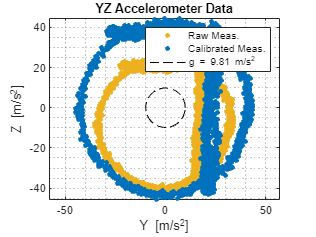

% Plot YZ data
figure;
plot(rawData(:, 2), rawData(:, 3), 'o', 'DisplayName', 'Raw Meas.', MarkerFaceColor=RGB_Orange, MarkerEdgeColor=RGB_Orange, MarkerSize=msize);
hold on;
plot(calibData(:, 2), calibData(:, 3), 'o', 'DisplayName', 'Calibrated Meas.', MarkerFaceColor=RGB_Blue, MarkerEdgeColor=RGB_Blue, MarkerSize=msize);
title('YZ Accelerometer Data');
xlabel(['Y [' units ']']);
ylabel(['Z [' units ']']);
legend;
grid minor;
axis equal;

% Plot the circle
plot(x_circle, y_circle, 'k--', 'LineWidth', 0.5, 'DisplayName', 'g = 9.81 m/s^2');

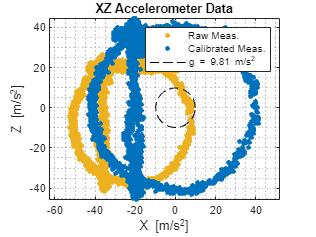

% Plot XZ data
figure;
plot(rawData(:, 1), rawData(:, 3), 'o', 'DisplayName', 'Raw Meas.', MarkerFaceColor=RGB_Orange, MarkerEdgeColor=RGB_Orange, MarkerSize=msize);
hold on;
plot(calibData(:, 1), calibData(:, 3), 'o', 'DisplayName', 'Calibrated Meas.', MarkerFaceColor=RGB_Blue, MarkerEdgeColor=RGB_Blue, MarkerSize=msize);
title('XZ Accelerometer Data');
xlabel(['X [' units ']']);
ylabel(['Z [' units ']']);
legend;
grid minor;
axis equal;


% Plot the circle
plot(x_circle, y_circle, 'k--', 'LineWidth', 0.5, 'DisplayName', 'g = 9.81 m/s^2');

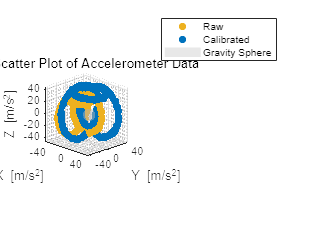

% Plot 3D scatter
figure;
scatter3(rawData(:, 1), rawData(:, 2), rawData(:, 3), 20, 'o', 'filled','DisplayName', 'Raw', MarkerFaceColor=RGB_Orange);
hold on;
scatter3(calibData(:, 1), calibData(:, 2), calibData(:, 3), 20, 'o', 'filled', 'DisplayName', 'Calibrated',MarkerFaceColor=RGB_Blue);
title('3D Scatter Plot of Accelerometer Data');
xlabel(['X [' units ']']);
ylabel(['Y [' units ']']);
zlabel(['Z [' units ']']);
legend;
grid minor;
axis equal;

% Plot sphere
[x, y, z] = sphere;
x = x * 9.8066;
y = y * 9.8066;
z = z * 9.8066;

% Specify the sphere colour
sphereColor = [.7, .7, .7];  % RGB colour values
surf(x, y, z, 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'DisplayName', 'Gravity Sphere', FaceColor=sphereColor);
% colormap(cool(256))
view(45,20)

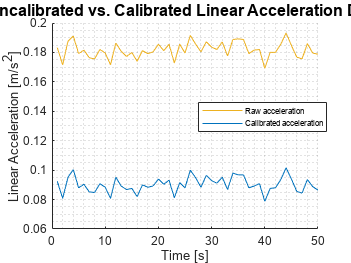

% Read raw and calibrated linear acceleration data
linearAccelData = dlmread('linearAcceldata_final.txt', '\t'); %#ok<DLMRD>
rawlinearAccelData = linearAccelData(:,1);
truelinearAccelData = linearAccelData(:,2);
time_units = 's';
t = 1:1:length(linearAccelData);

figure;
hold on
grid minor
plot(t,rawlinearAccelData,Color=RGB_Orange);
plot(t,truelinearAccelData,Color=RGB_Blue);
title('Uncalibrated vs. Calibrated Linear Acceleration Data','FontSize',12);
xlabel(['Time [' time_units ']']);
ylabel(['Linear Acceleration [' units ']']);
legend('Raw acceleration', "Calibrated acceleration", 'Location', 'best','FontSize',6, "Position", [0.60443,0.50022,0.28608,0.11168]);
print -depsc linearAccelPlot